# `Activity 1`

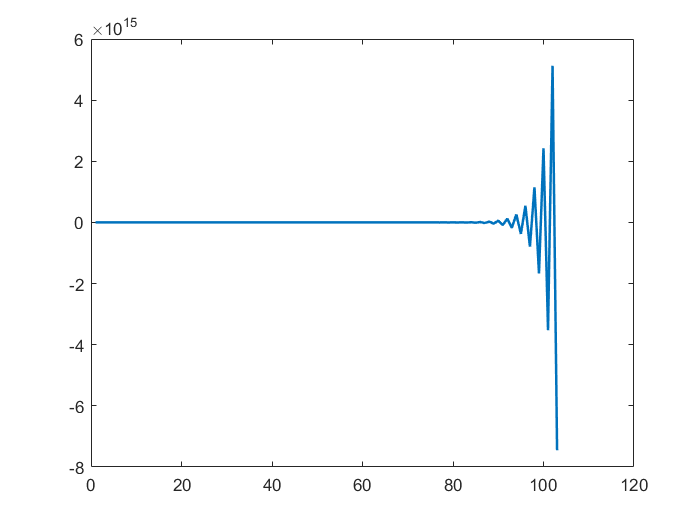

x = zeros(1,100);

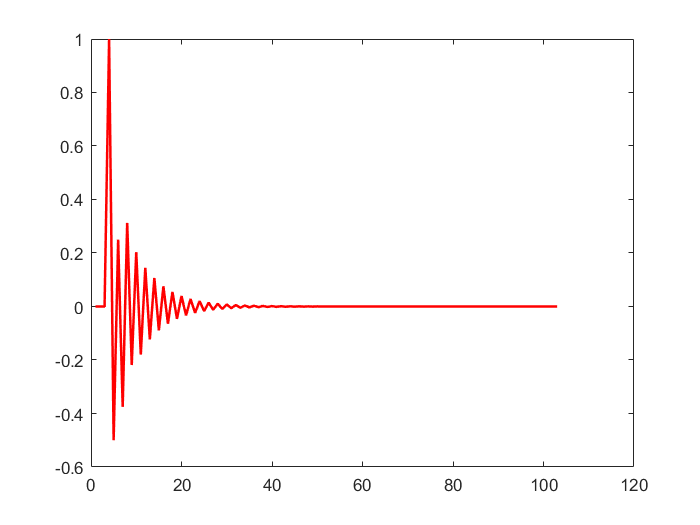

x(1)=1;
r = 0.5;
w = pi/3;
y=[0,0,0];
for i=1:100
   new = x(i)+2*r*cos(4*w)*y(end)-r*r*y(end-2);
   y = [y ,new];
end

plot(y,'r','LineWidth',1.5)

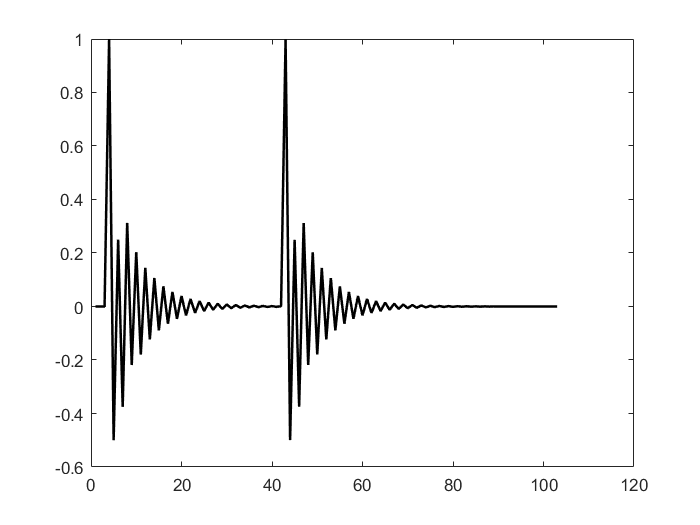

x = zeros(1,100);
x(1)=1;
x(40)=1;
r = 0.5;
w = pi/3;
y=[0,0,0];
for i=1:100
   new = x(i)+2*r*cos(4*w)*y(end)-(r^2)*y(end-2);
   y = [y ,new];
end

plot(y,'k','LineWidth',1.5)

#### 
$$y\left\lbrack n\right\rbrack =b_0 x\left\lbrack n\right\rbrack +b_1 x\left\lbrack n-1\right\rbrack +\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp -a_1 Y\left\lbrack n-1\right\rbrack -a_2 Y\left\lbrack n-2\right\rbrack -\ldotp \ldotp \ldotp \ldotp$$



$$a_0 =1$$



$$b_0 =1$$



$$a_1 =-2r\;\textrm{Cos}\left(\omega \right)$$



$$a_2 =r^2$$



$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack \;-2r\;\textrm{Cos}\left(\omega \right)Y\left\lbrack n-1\right\rbrack$$



$$\textrm{Let}\;\omega =\frac{\pi \;}{2}\;\;\textrm{and}\;r=0\ldotp 9$$



$$a_0 =1$$



$$b_{0\backslash } =1$$



$$a_1 =0$$



$$a_2 =0\ldotp 81$$


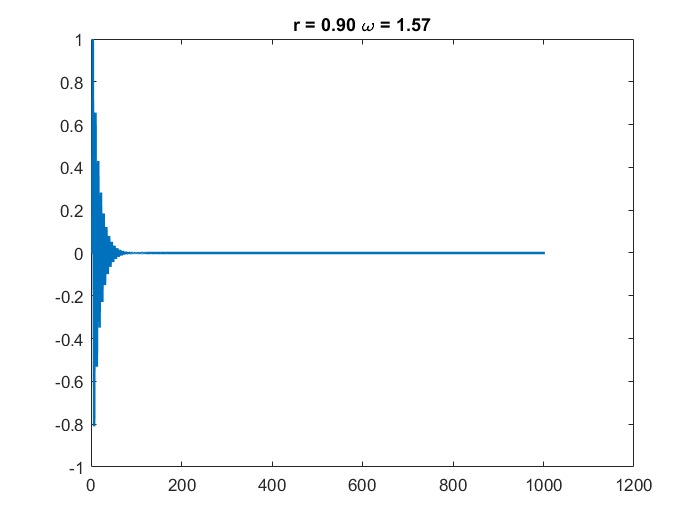

x = zeros(1,1000);
x(1)=1;

r = 0.9;
w = pi/2;
y = [0,0,0];

for i=1:1000
   new = x(i) + 2*r*cos(w)*y(end-1) - (r^2)*y(end-2);
   y = [y ,new];
end

figure()
plot(y,'LineWidth',1.5)
title_txt = sprintf('r = %.2f \\omega = %.2f',round(r,2),round(w,2));
title(title_txt)

### `Change w and r by changing Sliders`

r =0.73

r = 0.7300

w = 50   

w = 50

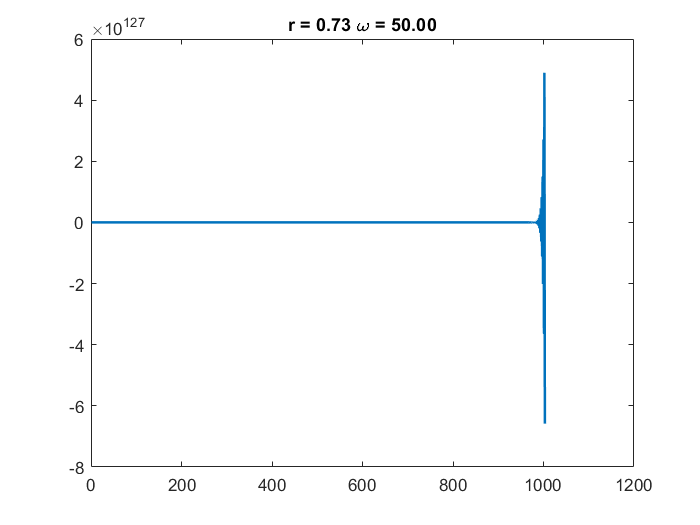

x = zeros(1,1000);
x(1)=1;

y = [0,0,0];

for i=1:1000
   new = x(i) + 2*r*cos(w)*y(end-1) - (r^2)*y(end-2);
   y = [y ,new];
end

figure()
plot(y,'LineWidth',1.5)
title_txt = sprintf('r = %.2f \\omega = %.2f',round(r,2),round(w,2));
title(title_txt)

### `Effect of R`

r = 0

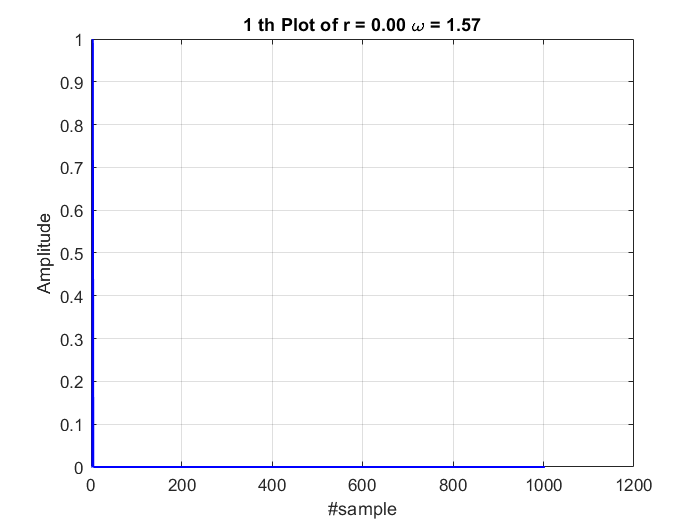

r = 0.1000

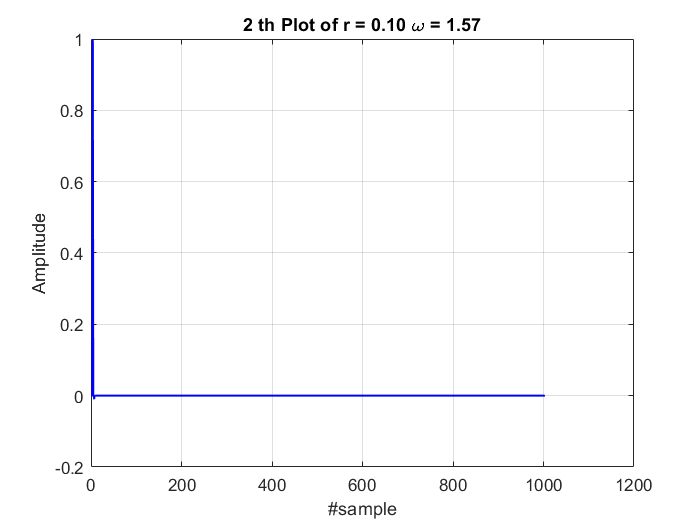

r = 0.2000

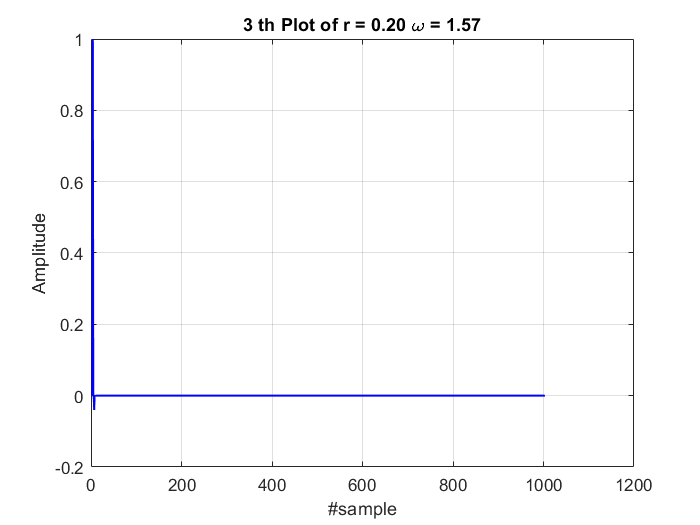

r = 0.3000

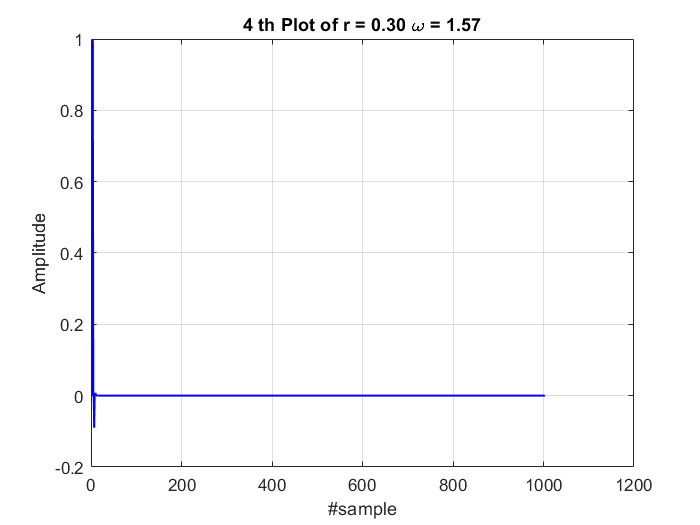

r = 0.4000

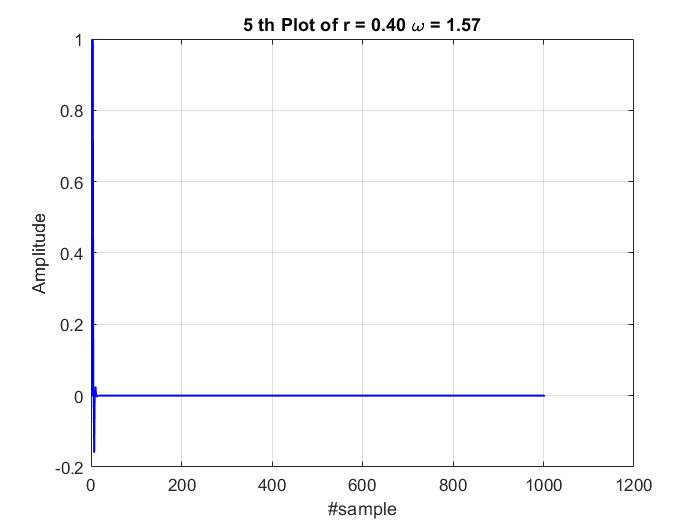

r = 0.5000

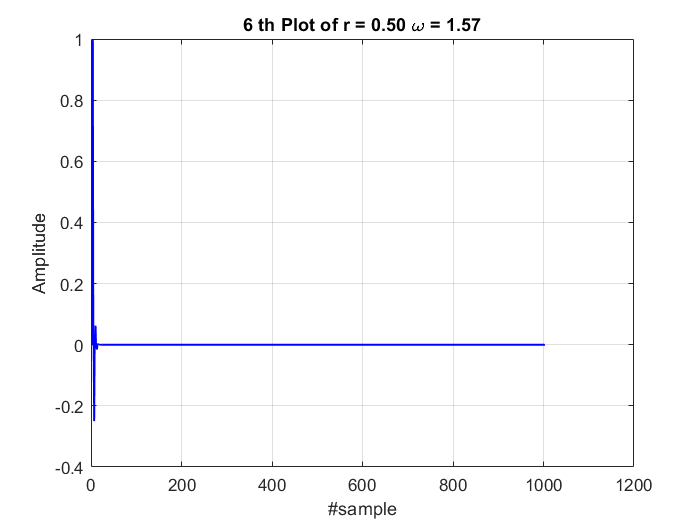

r = 0.6000

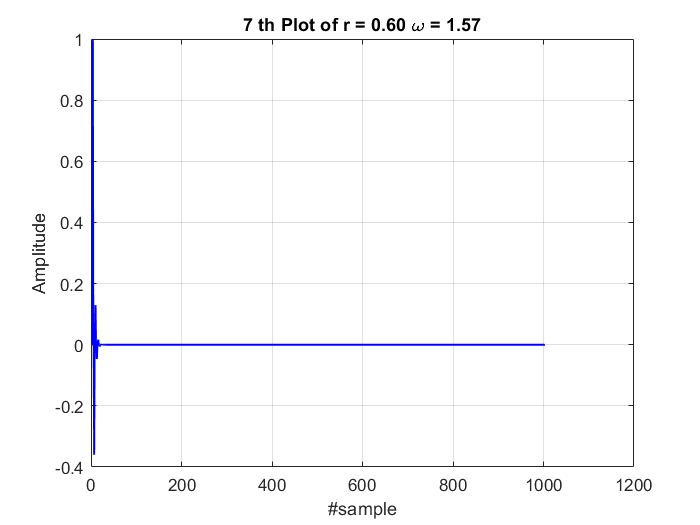

r = 0.7000

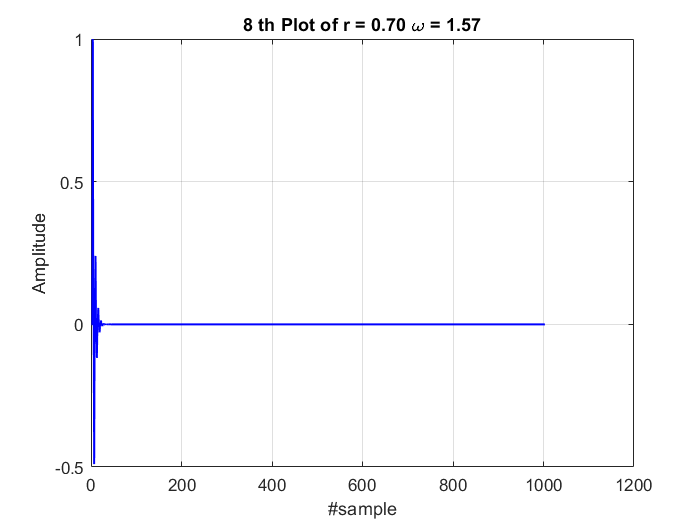

r = 0.8000

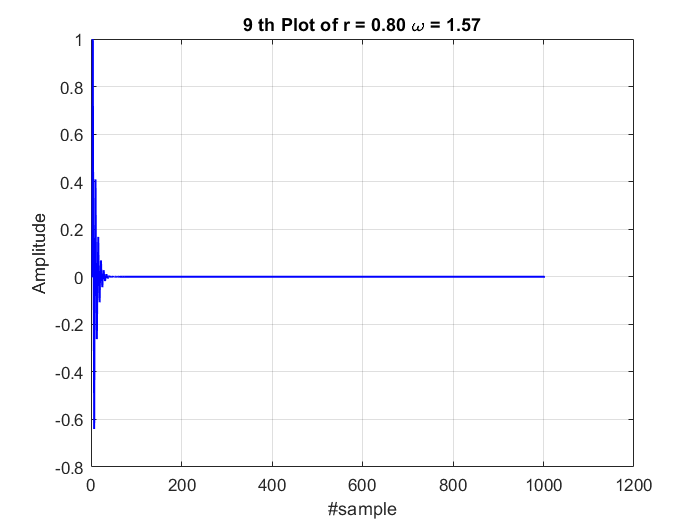

r = 0.9000

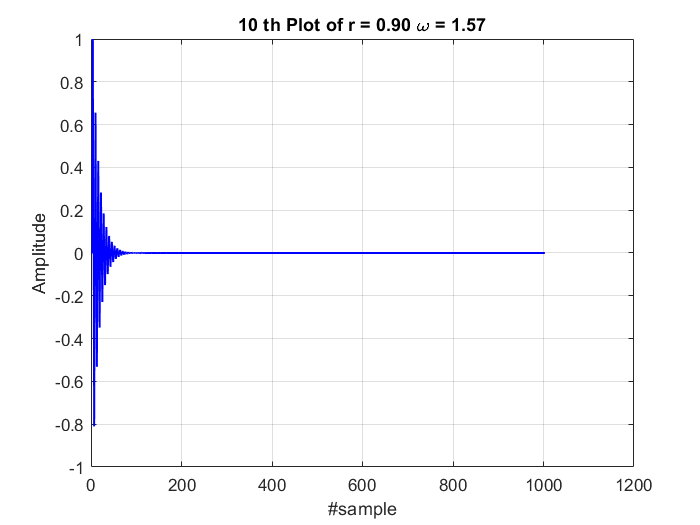

r = 1

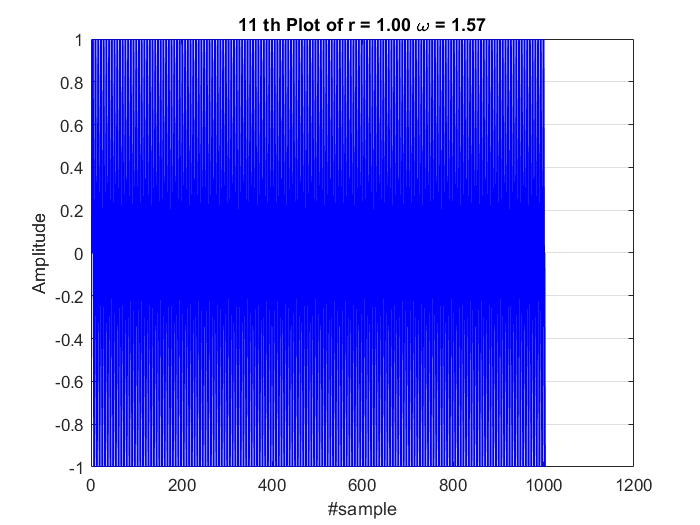

vec_r = 0:0.1:1;
w = pi/2;
for i= 1:length(vec_r)
    r = vec_r(i)
    display_grpah(i,r,w)
end

### `Effect of W`

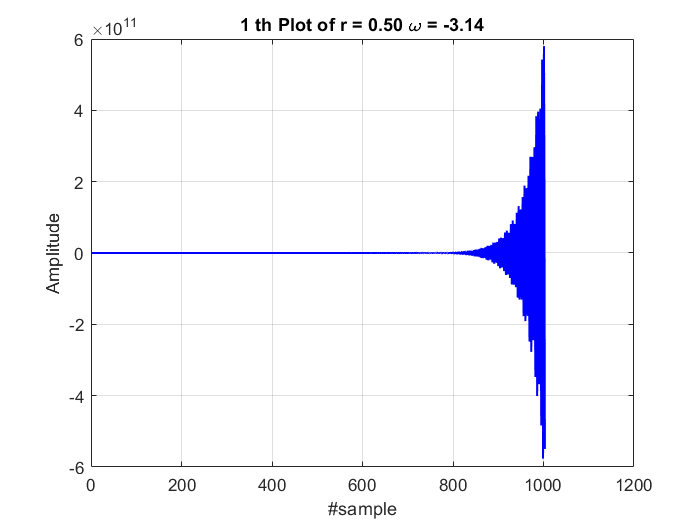

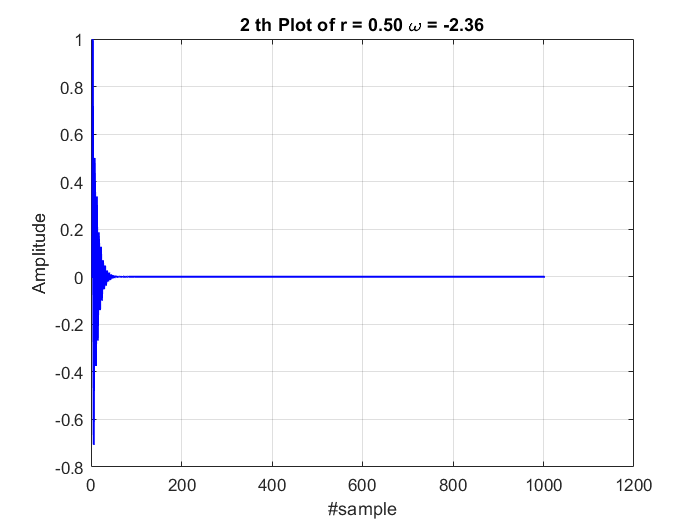

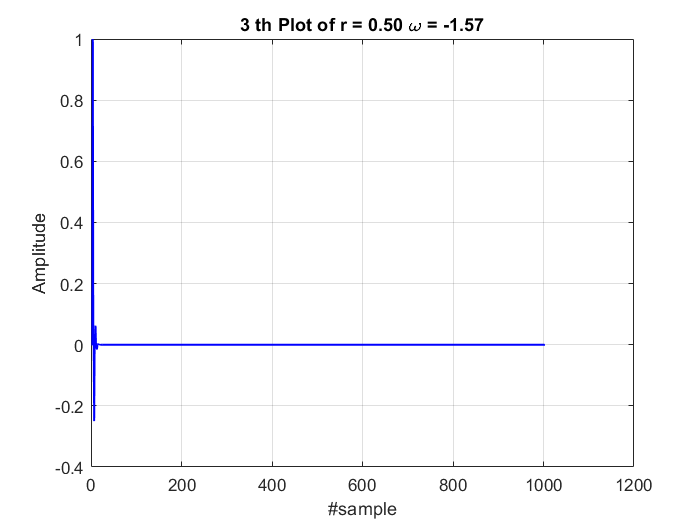

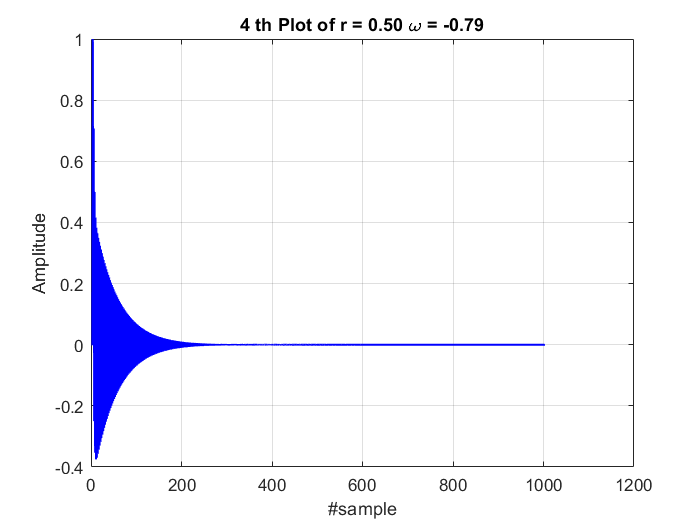

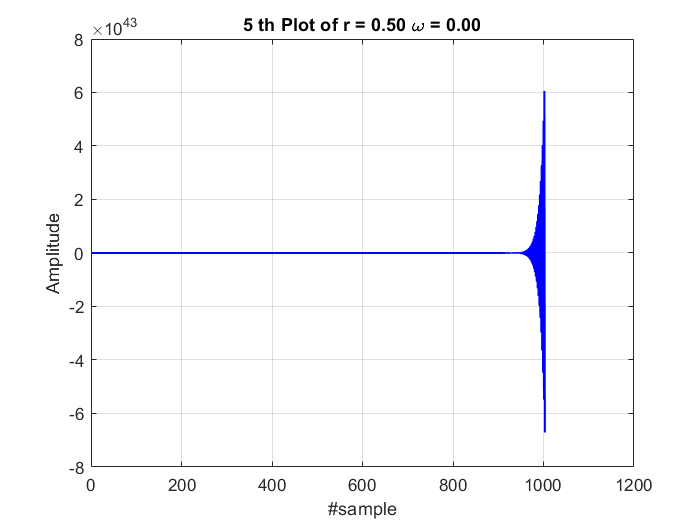

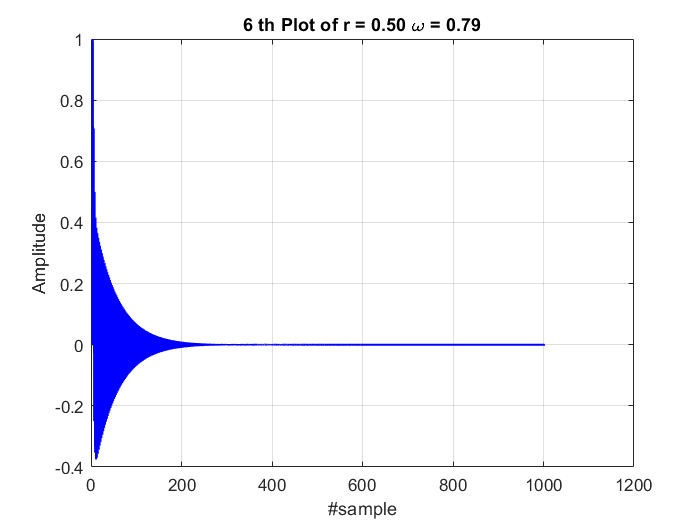

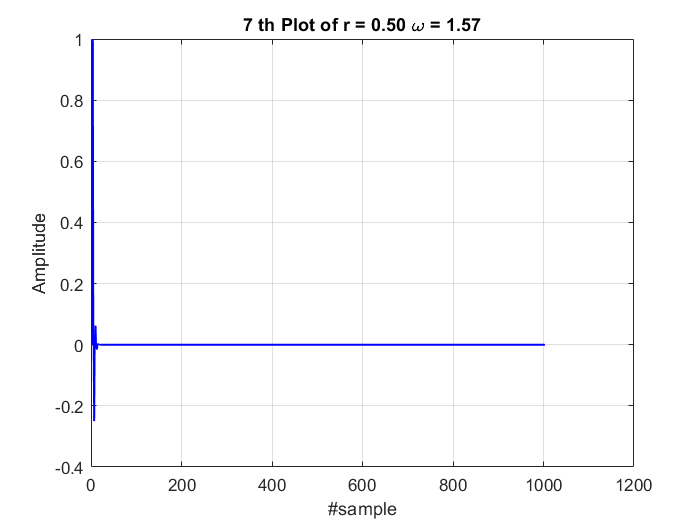

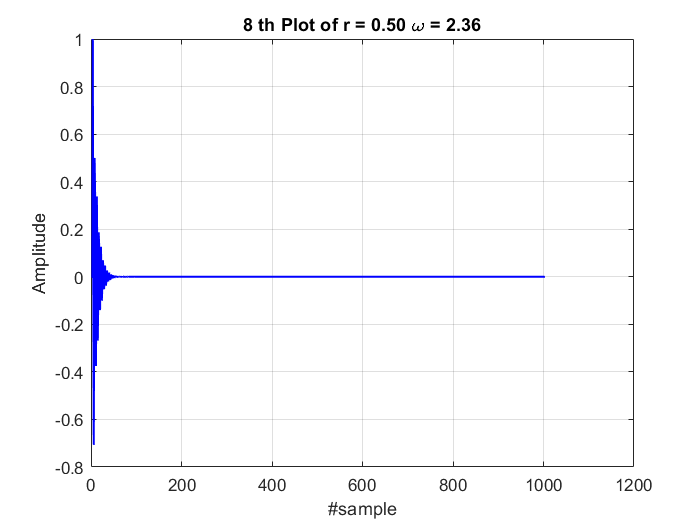

r = 0.5;
vec_w = -pi:pi/4:pi;
for j= 1:length(vec_w)
    w = vec_w(j);
    display_grpah(j,r,w)
end

function display_grpah(n,r, w)
    x = zeros(1,1000);
    x(1)=1;
    y = [0,0,0];
    
    for i=1:1000
       new = x(i) + 2*r*cos(w)*y(end-1) - (r^2)*y(end-2);
       y = [y ,new];
    end
    
    %cmap = hsv(12);
    figure()
    plot(y,'LineWidth',1.2,'Color','blue')
    title_txt = sprintf('%d th Plot of r = %.2f \\omega = %.2f',n,round(r,2),round(w,2));
    title(title_txt)
    grid on
    xlabel('#sample')
    ylabel('Amplitude')
end